# Решения [уравнения Шредингера](https://ru.wikipedia.org/wiki/Уравнение_Шрёдингера) в частных случаях

#### Свободная частица в [одномерном ящике](https://ru.wikipedia.org/wiki/Яма_с_бесконечными_стенками)


$$E_n =\frac{n^2 \pi^2 \hbar^2 }{2{\;m\;a}^2 },\;\;\;\;\;n=1,2,\ldotp \ldotp \ldotp$$



$$\psi_n \left(x\right)=\sqrt{\frac{2}{a}}\mathrm{sin}\;\frac{n\pi x}{a}$$


syms E(n) n hp m a psi(n) pi x
E(n)==n^2*pi^2*hp^2/(2*m*a^2)

$$ans = \text{E}\left(n\right)=\frac{{\mathrm{hp}}^{2}\,n^{2}\,\pi^{2}}{2\,a^{2}\,m}$$

psi(n)==sqrt(2/a)*sin(n*pi*x/a)

$$ans = \psi \left(n\right)=\sqrt{2}\,\sin\left(\frac{\pi \,n\,x}{a}\right)\,\sqrt{\frac{1}{a}}$$

#### Решения для случая постоянной [потенциальной энергии](https://ru.wikipedia.org/wiki/Потенциальная_энергия) $E_p$


$$\psi \left(x\right)=A\;e^{i\;k\;x} +B\;e^{-i\;k\;x} ,\;k=\frac{1}{\hbar }\sqrt{2m\left(E-E_p \right)},\mathrm{если}\;E>E_p$$


syms psi(x) A B k x m E E_p hp
psi(x)==A*exp(i*k*x)+B*exp(-i*k*x)

$$ans = \psi \left(x\right)=A\,{\mathrm{e}}^{k\,x\,\mathrm{i}}+B\,{\mathrm{e}}^{-k\,x\,\mathrm{i}}$$

k==1/hp*sqrt(2*m*(E-E_p))

$$ans = k=\frac{\sqrt{2}\,\sqrt{m\,\left(\text{E}-E_{p}\right)}}{\mathrm{hp}}$$


$$\psi \left(x\right)=C\;e^{\alpha x} +D\;e^{-\alpha x} ,\;k=\frac{1}{\hbar }\sqrt{2m\left(E-E_p \right)},\mathrm{если}\;E>E_p$$


syms psi(x) C D alpha
psi(x)==C*exp(alpha*x)+D*exp(-alpha*x)

$$ans = \psi \left(x\right)=C\,{\mathrm{e}}^{\alpha \,x}+\text{D}\,{\mathrm{e}}^{-\alpha \,x}$$

alpha==1/hp*sqrt(2*m*(E_p-E))

$$ans = \alpha =\frac{\sqrt{2}\,\sqrt{-m\,\left(\text{E}-E_{p}\right)}}{\mathrm{hp}}$$

#### Линейный [гармонический осциллятор](https://ru.wikipedia.org/wiki/Квантовый_гармонический_осциллятор)


$$E_n \left(x\right)=\frac{1}{2}k\;x^2 =\frac{1}{2}m\;\omega^2 x^2$$



$$E_n =\left(n+\frac{1}{2}\right)\hbar \omega$$
                  
$$n=0,1,2,\ldotp \ldotp \ldotp$$



$$\psi_n \left(x\right)=N_n H_n \left(\alpha x\right)e^{-\frac{1}{2}\alpha^2 x^2 }$$


$\alpha =\sqrt{\frac{m\omega }{\hbar }}={\left(\sqrt{\frac{k\;m}{\hbar }}\right)}^{\frac{1}{2}}$              $H_n \left(x\right)$= [полином Эрмита](https://ru.wikipedia.org/wiki/Многочлены_Эрмита)

clear
syms E(n) k x m omega hp
E(n)==1/2*k*x^2==1/2*m*omega^2*x^2

$$ans = \left(\text{E}\left(n\right)=\frac{k\,x^{2}}{2}\right)=\frac{m\,\omega^{2}\,x^{2}}{2}$$

E(n)==(n+1/2)*hp*omega

$$ans = \text{E}\left(n\right)=\mathrm{hp}\,\omega \,\left(n+\frac{1}{2}\right)$$

syms alpha x N(n) n pi
N(n)=(alpha/(2^n*factorial(n)*sqrt(pi)))^(1/2)

$$N(n) = \sqrt{\frac{\alpha }{2^{n}\,\sqrt{\pi }\,n!}}$$

psi(n)=N(n)*hermiteH(n,alpha*x)*exp(-1/2*alpha^2*x^2)

$$psi(n) = {\mathrm{e}}^{-\frac{\alpha^{2}\,x^{2}}{2}}\,\mathrm{hermiteH}\left(n,\alpha \,x\right)\,\sqrt{\frac{\alpha }{2^{n}\,\sqrt{\pi }\,n!}}$$

for n=0:3
    psi1(n+1)=psi(n);
end
psi1.'

$$ans = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\,\sqrt{\frac{\alpha }{\sqrt{\pi }}}\\ 2\,\alpha \,x\,\sigma_{1}\,\sqrt{\frac{\alpha }{2\,\sqrt{\pi }}}\\ \sigma_{1}\,\left(4\,\alpha^{2}\,x^{2}-2\right)\,\sqrt{\frac{\alpha }{8\,\sqrt{\pi }}}\\ -\sigma_{1}\,\left(12\,\alpha \,x-8\,\alpha^{3}\,x^{3}\right)\,\sqrt{\frac{\alpha }{48\,\sqrt{\pi }}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\alpha^{2}\,x^{2}}{2}} \end{array}$$

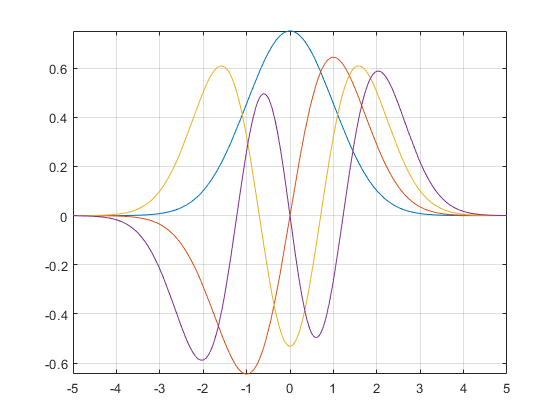

fplot(subs(psi1,alpha,1)),grid on

#### Коэффициента пропускания и отражения [потенциальной ступеньки](https://ru.wikipedia.org/wiki/Потенциальная_ступенька)

clear
syms E E_p k1 k2 m hp S_prop S_pad S_otr T R
E>E_p

$$ans = E_{p}<\text{E}$$

k1==1/hp*sqrt(2*m*E)

$$ans = k_{1}=\frac{\sqrt{2}\,\sqrt{\text{E}\,m}}{\mathrm{hp}}$$

k2==1/hp*sqrt(2*m*(E-E_p))

$$ans = k_{2}=\frac{\sqrt{2}\,\sqrt{m\,\left(\text{E}-E_{p}\right)}}{\mathrm{hp}}$$

T==abs(S_prop)/abs(S_pad)==4*k1*k2/(k1+k2)^2

$$ans = \left(T=\frac{\left|S_{\mathrm{prop}}\right|}{\left|S_{\mathrm{pad}}\right|}\right)=\frac{4\,k_{1}\,k_{2}}{{\left(k_{1}+k_{2}\right)}^{2}}$$

R==abs(S_otr)/abs(S_pad)==(k1-k2)^2/(k1+k2)^2

$$ans = \left(R=\frac{\left|S_{\mathrm{otr}}\right|}{\left|S_{\mathrm{pad}}\right|}\right)=\frac{{\left(k_{1}-k_{2}\right)}^{2}}{{\left(k_{1}+k_{2}\right)}^{2}}$$

S = [поток вероятности](https://ru.wikipedia.org/wiki/Ток_вероятности)

T+R==1

$$ans = R+T=1$$

#### Коэффициент пропускания [барьера](https://ru.wikipedia.org/wiki/Потенциальный_барьер) высотой $E_p$ и шириной $\alpha$

syms alpha a E E_p T
T==(1+E_p^2*sinh(alpha)^2*a/(4*E*(E_p-E)))^(-1)         % (E<E_p)

$$ans = T=-\frac{1}{\frac{{E_{p}}^{2}\,a\,{\sinh\left(\alpha \right)}^{2}}{4\,\text{E}\,\left(\text{E}-E_{p}\right)}-1}$$

T=(1+E_p^2*sin(alpha)^2*a/(4*E*(E-E_p)))^(-1)        % (E>E_p)

$$T = \frac{1}{\frac{{E_{p}}^{2}\,a\,{\sin\left(\alpha \right)}^{2}}{4\,\text{E}\,\left(\text{E}-E_{p}\right)}+1}$$

alpha==sqrt(2*m*(E_p-E))/hp

$$ans = \alpha =\frac{\sqrt{2}\,\sqrt{-m\,\left(\text{E}-E_{p}\right)}}{\mathrm{hp}}$$

#### Плотность состояния одной частицы в ящике объемом $V$

syms g(x) N E V m E p d(f,x,n) c nu
g(E)==d(N,E,1)==4*pi*V*(2*m^3)^(1/2)*E^(1/2)/hp^3

$$ans = \left(g\left(\text{E}\right)=d\left(N,\text{E},1\right)\right)=\frac{4\,\pi \,\sqrt{\text{E}}\,V\,\sqrt{2\,m^{3}}}{{\mathrm{hp}}^{3}}$$

% N = число уровней энергии

g(p)==d(N,p,1)==4*pi*V*p^2/hp^3

$$ans = \left(g\left(p\right)=d\left(N,p,1\right)\right)=\frac{4\,\pi \,V\,p^{2}}{{\mathrm{hp}}^{3}}$$

% p = импульс

g(nu)==d(N,nu,1)==4*pi*V*nu^2/c^3

$$ans = \left(g\left(\nu \right)=d\left(N,\nu ,1\right)\right)=\frac{4\,\pi \,V\,\nu^{2}}{c^{3}}$$

% nu = частота
% c = фазовая скорость